# **Analyse de la similarité des synergies musculaires**

## Objectif du script

Ce script MATLAB a pour objectif d'analyser et de comparer les synergies musculaires entre trois groupes différents :

- Les sujets asymptomatiques (n=20)

- Les sujets pré-opératoires (n=20)

- Les sujets post-opératoires (n=20, les mêmes que les pré-opératoires)

L'analyse se concentre sur deux synergies musculaires extraites pour chaque sujet et utilise la similarité cosinus comme mesure de comparaison.

## Principe de la similarité cosinus

La similarité cosinus est une mesure qui quantifie la similitude entre deux vecteurs en calculant le cosinus de l'angle entre eux. Cette mesure est particulièrement utile dans notre contexte car :

- Elle est indépendante de la magnitude des vecteurs et se concentre uniquement sur leur orientation

- Sa valeur est comprise entre -1 et 1 (dans le cas de coordonnées positives, entre 0 et 1)

- Une valeur proche de 1 indique des vecteurs très similaires

- Une valeur proche de 0 indique des vecteurs perpendiculaires (très différents)

Dans le contexte des synergies musculaires, chaque synergie est représentée comme un vecteur où chaque dimension correspond à l'activation d'un muscle spécifique. La similarité cosinus nous permet donc de quantifier à quel point deux patrons d'activation musculaire sont similaires.

## Structure de l'analyse

Le script effectue plusieurs niveaux d'analyse :

**1. Calcul des synergies moyennes asymptomatiques**

- Les synergies des 20 sujets asymptomatiques sont séparées et moyennées

- Ces moyennes servent de référence pour les comparaisons

**2. Comparaisons individuelles**

Pour chaque sujet pré et post-opératoire, le script calcule 4 valeurs de similarité :

- Synergie 1 du sujet vs Synergie 1 asymptomatique moyenne

- Synergie 2 du sujet vs Synergie 2 asymptomatique moyenne

**3. Tests statistiques**

Le script réalise trois types de tests statistiques :

- **Tests indépendants** (asymptomatiques vs pré-opératoires) : Ces tests comparent les groupes indépendants de sujets avec le test t de Student pour échantillons indépendants

- **Tests indépendants** (asymptomatiques vs post-opératoires) : Même méthode que ci-dessus

- **Tests appariés** (pré-opératoires vs post-opératoires) : Ces tests comparent les mesures sur les mêmes sujets avant et après l'opération avec le test t de Student pour échantillons appariés

## Interprétation des résultats

Les résultats permettent de répondre à plusieurs questions cliniques importantes :

- **Les synergies des patients pré-opératoires diffèrent-elles des sujets asymptomatiques ?**

- Si les p-values des tests asymptomatiques vs pré-opératoires sont significatives (<0.05), cela indique une différence systématique dans les patrons d'activation musculaire.

- **L'intervention chirurgicale normalise-t-elle les synergies musculaires ?**

- Si les p-values des tests asymptomatiques vs post-opératoires ne sont pas significatives (≥0.05), cela suggère que l'intervention a permis de rapprocher les synergies des patients de celles des sujets asymptomatiques.

- **Y a-t-il une amélioration significative après l'intervention ?**

- Si les p-values des tests pré-opératoires vs post-opératoires sont significatives (<0.05), cela indique un changement systématique dans les synergies après l'opération.

## Visualisations

Le script génère plusieurs visualisations pour faciliter l'interprétation :

- **Profils moyens des synergies asymptomatiques** : Graphiques à barres montrant l'activation moyenne de chaque muscle avec des barres d'erreur.

- **Similarités par sujet** : Graphiques en barres montrant les similarités cosinus pour chaque sujet et chaque type de comparaison.

- **Moyennes des similarités** : Graphique comparant les moyennes des similarités entre les groupes pré et post-opératoires.

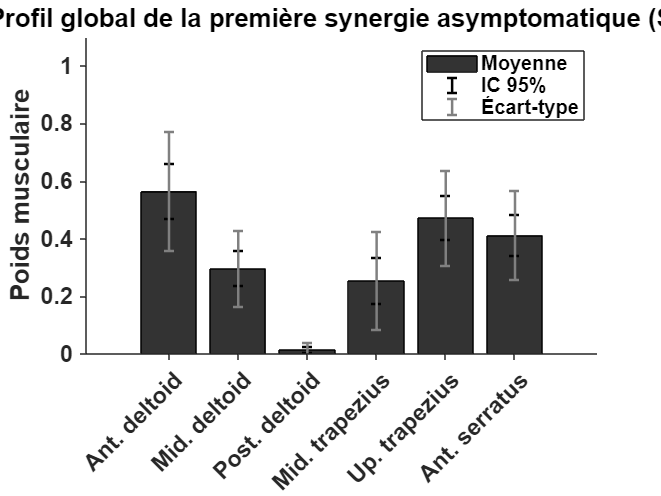

% Définition des muscles analysés
noms_muscles = {'Ant. deltoid', 'Mid. deltoid', 'Post. deltoid', ...
    'Mid. trapezius', 'Up. trapezius', 'Ant. serratus'};
n_asymp = 20;  % nombre de sujets asymptomatiques
n_pre_post = 20;  % nombre de sujets pré et post-opératoires
n_muscles = 6;  % nombre de muscles

% Définition des couleurs personnalisées
dark_black = [0.2, 0.2, 0.2];   % Asymptomatique S1
light_black = [0.7, 0.7, 0.7];  % Asymptomatique S2
dark_red = [0.6, 0, 0];         % Pré-op S1
light_red = [1.0, 0.6, 0.6];    % Pré-op S2
dark_blue = [0, 0, 0.5];        % Post-op S1
light_blue = [0.6, 0.8, 1.0];   % Post-op S2

%% Charger les données
% Charger les matrices de synergies ici (ces lignes supposent que les variables sont déjà définies)
W_asymp = Profilglobalsynergies;  % Profil global des synergies asymptomatiques
W_pre = Profilglobalsynergiespr;  % Profil global des synergies pré-opératoires
W_post = Profilglobalsynergiespost;  % Profil global des synergies post-opératoires

%% Définition de la fonction de similarité cosinus
function similarity = cosSimilarity(v1, v2)
    % Calcule la similarité cosinus entre deux vecteurs
    similarity = dot(v1, v2) / (norm(v1) * norm(v2));
end

%% Séparation des synergies asymptomatiques
synergy1_asymp = zeros(n_muscles, n_asymp);
synergy2_asymp = zeros(n_muscles, n_asymp);

for i = 1:n_asymp
    synergy1_asymp(:, i) = W_asymp(:, (i-1)*2 + 1);  % colonnes impaires (1,3,...)
    synergy2_asymp(:, i) = W_asymp(:, (i-1)*2 + 2);  % colonnes paires (2,4,...)
end

% Calcul des moyennes des synergies asymptomatiques
mean_synergy1_asymp = mean(synergy1_asymp, 2);
mean_synergy2_asymp = mean(synergy2_asymp, 2);

%% Séparation des synergies pré-opératoires
synergy1_pre = zeros(n_muscles, n_pre_post);
synergy2_pre = zeros(n_muscles, n_pre_post);

for i = 1:n_pre_post
    synergy1_pre(:, i) = W_pre(:, (i-1)*2 + 1);
    synergy2_pre(:, i) = W_pre(:, (i-1)*2 + 2);
end

%% Séparation des synergies post-opératoires
synergy1_post = zeros(n_muscles, n_pre_post);
synergy2_post = zeros(n_muscles, n_pre_post);

for i = 1:n_pre_post
    synergy1_post(:, i) = W_post(:, (i-1)*2 + 1);
    synergy2_post(:, i) = W_post(:, (i-1)*2 + 2);
end

%% Calcul des similarités cosinus entre synergies asymptomatiques et pré-opératoires
% Initialisation des matrices de résultats
similarity_pre_S1_asymp_S1 = zeros(n_pre_post, 1);
similarity_pre_S2_asymp_S2 = zeros(n_pre_post, 1);

% Calcul des similarités pour chaque sujet pré-opératoire
for i = 1:n_pre_post
    % Comparaison synergie 1 du sujet i avec la synergie 1 moyenne asymptomatique
    similarity_pre_S1_asymp_S1(i) = cosSimilarity(synergy1_pre(:, i), mean_synergy1_asymp);
    
    % Comparaison synergie 2 du sujet i avec la synergie 2 moyenne asymptomatique
    similarity_pre_S2_asymp_S2(i) = cosSimilarity(synergy2_pre(:, i), mean_synergy2_asymp);
end

%% Calcul des similarités cosinus entre synergies asymptomatiques et post-opératoires
% Initialisation des matrices de résultats
similarity_post_S1_asymp_S1 = zeros(n_pre_post, 1);
similarity_post_S2_asymp_S2 = zeros(n_pre_post, 1);

% Calcul des similarités pour chaque sujet post-opératoire
for i = 1:n_pre_post
    % Comparaison synergie 1 du sujet i avec la synergie 1 moyenne asymptomatique
    similarity_post_S1_asymp_S1(i) = cosSimilarity(synergy1_post(:, i), mean_synergy1_asymp);
    
    % Comparaison synergie 2 du sujet i avec la synergie 2 moyenne asymptomatique
    similarity_post_S2_asymp_S2(i) = cosSimilarity(synergy2_post(:, i), mean_synergy2_asymp);
end

%% Affichage des profils moyens des synergies asymptomatiques
% Calcul des statistiques pour les synergies asymptomatiques
t_val = tinv(0.975, n_asymp-1);  % valeur t pour IC à 95% et n-1 degrés de liberté
std_synergy1_asymp = std(synergy1_asymp, 0, 2);
sem_synergy1_asymp = std_synergy1_asymp / sqrt(n_asymp);
IC_synergy1_asymp = t_val * sem_synergy1_asymp;

std_synergy2_asymp = std(synergy2_asymp, 0, 2);
sem_synergy2_asymp = std_synergy2_asymp / sqrt(n_asymp);
IC_synergy2_asymp = t_val * sem_synergy2_asymp;

% Synergie 1 asymptomatique
figure;
x = 1:n_muscles;
bar(mean_synergy1_asymp, 'FaceColor', dark_black)
hold on
errorbar(x, mean_synergy1_asymp, IC_synergy1_asymp, 'k', 'LineStyle', 'none', 'LineWidth', 1.5) % IC
errorbar(x, mean_synergy1_asymp, std_synergy1_asymp, 'Color', [0.5 0.5 0.5], 'LineStyle', 'none', 'LineWidth', 1.5) % STD
title('Profil global de la première synergie asymptomatique (S1)', 'FontSize', 18, 'FontWeight', 'bold');
ylabel('Poids musculaire', 'FontSize', 14, 'FontWeight', 'bold');
xticks(1:n_muscles)
xticklabels(noms_muscles)
xtickangle(45)
ylim([0 1.1])
set(gca, 'XTick', 1:n_muscles, ...
    'XTickLabel', noms_muscles, ...
    'FontSize', 14, ...
    'FontWeight', 'bold', ...
    'TickDir', 'out', ...
    'Box', 'off');
legend('Moyenne', 'IC 95%', 'Écart-type', 'Location', 'northeast', 'FontSize', 12)
hold off

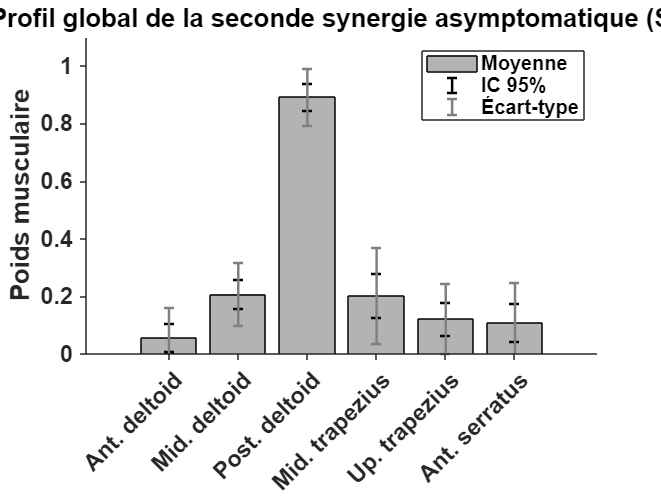


% Synergie 2 asymptomatique
figure;
x = 1:n_muscles;
bar(mean_synergy2_asymp, 'FaceColor', light_black)
hold on
errorbar(x, mean_synergy2_asymp, IC_synergy2_asymp, 'k', 'LineStyle', 'none', 'LineWidth', 1.5) % IC
errorbar(x, mean_synergy2_asymp, std_synergy2_asymp, 'Color', [0.5 0.5 0.5], 'LineStyle', 'none', 'LineWidth', 1.5) % STD
title('Profil global de la seconde synergie asymptomatique (S2)', 'FontSize', 18, 'FontWeight', 'bold');
ylabel('Poids musculaire', 'FontSize', 14, 'FontWeight', 'bold');
xticks(1:n_muscles)
xticklabels(noms_muscles)
xtickangle(45)
ylim([0 1.1])
set(gca, 'XTick', 1:n_muscles, ...
    'XTickLabel', noms_muscles, ...
    'FontSize', 14, ...
    'FontWeight', 'bold', ...
    'TickDir', 'out', ...
    'Box', 'off');
legend('Moyenne', 'IC 95%', 'Écart-type', 'Location', 'northeast', 'FontSize', 12)
hold off

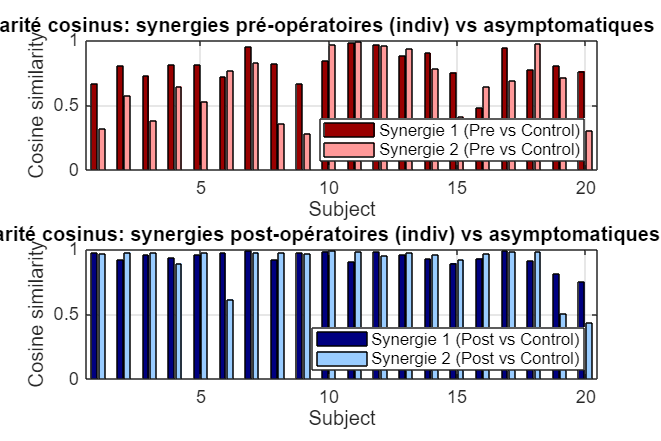



%% Affichage des résultats de similarité
% Création d'un tableau de résultats pour les sujets pré-opératoires
figure;
subplot(2,1,1);
data_pre = [similarity_pre_S1_asymp_S1, similarity_pre_S2_asymp_S2];
barColors = {dark_red, light_red}; 
b = bar(data_pre);
for k = 1:size(data_pre,2)
    b(k).FaceColor = barColors{k}; 
end
title('Similarité cosinus: synergies pré-opératoires (indiv) vs asymptomatiques (global)', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Subject', 'FontSize', 11);
ylabel('Cosine similarity', 'FontSize', 11);
legend('Synergie 1 (Pre vs Control)', 'Synergie 2 (Pre vs Control)', 'FontSize', 10, 'Location', 'southeast');
ylim([0 1]);
grid on;
set(gca, 'FontSize', 11)

% Création d'un tableau de résultats pour les sujets post-opératoires
subplot(2,1,2);
data_post = [similarity_post_S1_asymp_S1, similarity_post_S2_asymp_S2];
barColors = {dark_blue light_blue};
b = bar(data_post);
for k = 1:size(data_post,2)
    b(k).FaceColor = barColors{k};
end
title('Similarité cosinus: synergies post-opératoires (indiv) vs asymptomatiques (global)', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Subject', 'FontSize', 11);
ylabel('Cosine similarity', 'FontSize', 11);
legend('Synergie 1 (Post vs Control)', 'Synergie 2 (Post vs Control)', 'FontSize', 10, 'Location', 'southeast');
ylim([0 1]);
grid on;
set(gca, 'FontSize', 11)

% Ajuster la figure pour une meilleure visibilité
set(gcf, 'Position', [100, 100, 1200, 800]);

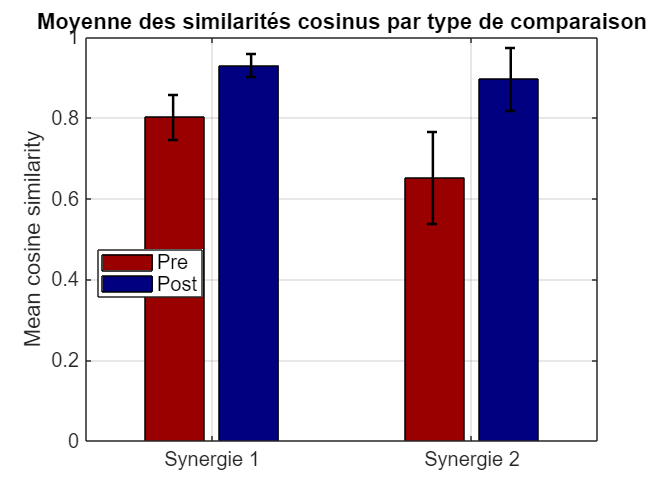


%% Affichage des moyennes des similarités
% Calcul des moyennes et écarts-types des similarités
mean_similarity_pre = mean(data_pre);
std_similarity_pre = std(data_pre);
sem_similarity_pre = std_similarity_pre / sqrt(n_pre_post); % Erreur standard de la moyenne
IC_similarity_pre = tinv(0.975, n_pre_post-1) * sem_similarity_pre; % Intervalle de confiance à 95%

mean_similarity_post = mean(data_post);
std_similarity_post = std(data_post);
sem_similarity_post = std_similarity_post / sqrt(n_pre_post); % Erreur standard de la moyenne
IC_similarity_post = tinv(0.975, n_pre_post-1) * sem_similarity_post; % Intervalle de confiance à 95%

% Création d'une figure pour les moyennes
figure;
comparison_data = [mean_similarity_pre; mean_similarity_post]';

% Création des barres avec les couleurs spécifiées
b = bar(comparison_data);
b(1).FaceColor = dark_red;   % Pré-op
b(2).FaceColor = dark_blue;  % Post-op

hold on;

% Ajout des barres d'erreur (intervalle de confiance à 95%)
x = 1:2;
errorbar(x-0.15, comparison_data(:,1), IC_similarity_pre, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(x+0.15, comparison_data(:,2), IC_similarity_post, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

title('Moyenne des similarités cosinus par type de comparaison', 'FontSize', 16, 'FontWeight', 'bold');
xticks(1:2);
xticklabels({'Synergie 1', 'Synergie 2'});
ylabel('Mean cosine similarity', 'FontSize', 11);
legend('Pre', 'Post', 'Location', 'best', 'FontSize', 12);
ylim([0 1]);
grid on;
set(gca, 'FontSize', 12);


% Affichage des résultats numériques
fprintf('\n===== RÉSULTATS DES SIMILARITÉS COSINUS =====\n\n');


===== RÉSULTATS DES SIMILARITÉS COSINUS =====



fprintf('Moyennes et écarts-types des similarités cosinus:\n');

Moyennes et écarts-types des similarités cosinus:


fprintf('-----------------------------------------------------------\n');

-----------------------------------------------------------


fprintf('| Comparaison    | Pré-opératoire     | Post-opératoire    |\n');

| Comparaison    | Pré-opératoire     | Post-opératoire    |


fprintf('-----------------------------------------------------------\n');

-----------------------------------------------------------


fprintf('| S1 vs S1 asymp | %.3f ± %.3f      | %.3f ± %.3f      |\n', mean_similarity_pre(1), std_similarity_pre(1), mean_similarity_post(1), std_similarity_post(1));

| S1 vs S1 asymp | 0.802 ± 0.121      | 0.930 ± 0.060      |


fprintf('| S2 vs S2 asymp | %.3f ± %.3f      | %.3f ± %.3f      |\n', mean_similarity_pre(2), std_similarity_pre(2), mean_similarity_post(2), std_similarity_post(2));

| S2 vs S2 asymp | 0.652 ± 0.246      | 0.896 ± 0.167      |


fprintf('-----------------------------------------------------------\n');

-----------------------------------------------------------



%% Tests statistiques pour comparer les similarités
% 1. Comparaison asymptomatiques vs pré (tests indépendants)
% 2. Comparaison asymptomatiques vs post (tests indépendants)
% 3. Comparaison pré vs post (tests appariés)

% Création de matrices pour stocker les p-values
p_values_asymp_pre = zeros(2, 1);  % asympt vs pre (indépendant)
p_values_asymp_post = zeros(2, 1); % asympt vs post (indépendant)
p_values_pre_post = zeros(2, 1);   % pre vs post (apparié)

% Pour les tests asymptomatiques vs pré/post, nous calculons d'abord les similarités individuelles
% entre chaque sujet asymptomatique et la moyenne asymptomatique

% Calcul des similarités pour chaque sujet asymptomatique vs moyenne
sim_asymp_S1_vs_mean_S1 = zeros(n_asymp, 1);
sim_asymp_S2_vs_mean_S2 = zeros(n_asymp, 1);

for i = 1:n_asymp
    sim_asymp_S1_vs_mean_S1(i) = cosSimilarity(synergy1_asymp(:,i), mean_synergy1_asymp);
    sim_asymp_S2_vs_mean_S2(i) = cosSimilarity(synergy2_asymp(:,i), mean_synergy2_asymp);
end

% TESTS ANOVA
fprintf('\n===== ANALYSE DE VARIANCE (ANOVA) =====\n\n');


===== ANALYSE DE VARIANCE (ANOVA) =====




% Préparation des données pour ANOVA - Synergie 1
data_S1_anova = [sim_asymp_S1_vs_mean_S1; similarity_pre_S1_asymp_S1; similarity_post_S1_asymp_S1];
groups_S1 = [ones(length(sim_asymp_S1_vs_mean_S1), 1); 
             2*ones(length(similarity_pre_S1_asymp_S1), 1); 
             3*ones(length(similarity_post_S1_asymp_S1), 1)];

% Préparation des données pour ANOVA - Synergie 2
data_S2_anova = [sim_asymp_S2_vs_mean_S2; similarity_pre_S2_asymp_S2; similarity_post_S2_asymp_S2];
groups_S2 = [ones(length(sim_asymp_S2_vs_mean_S2), 1); 
             2*ones(length(similarity_pre_S2_asymp_S2), 1); 
             3*ones(length(similarity_post_S2_asymp_S2), 1)];

% ANOVA pour Synergie 1
[p_anova_S1, tbl_S1, stats_S1] = anova1(data_S1_anova, groups_S1, 'off');
F_stat_S1 = tbl_S1{2,5};
df_between_S1 = tbl_S1{2,3};
df_within_S1 = tbl_S1{3,3};

% ANOVA pour Synergie 2
[p_anova_S2, tbl_S2, stats_S2] = anova1(data_S2_anova, groups_S2, 'off');
F_stat_S2 = tbl_S2{2,5};
df_between_S2 = tbl_S2{2,3};
df_within_S2 = tbl_S2{3,3};

% Affichage des résultats ANOVA
fprintf('ANOVA À UN FACTEUR - COMPARAISON DES TROIS GROUPES\n');

ANOVA À UN FACTEUR - COMPARAISON DES TROIS GROUPES


fprintf('==================================================\n');

fprintf('| Synergie | F-statistic | df | p-value | Interprétation |\n');

| Synergie | F-statistic | df | p-value | Interprétation |


fprintf('==================================================\n');


% Synergie 1
if p_anova_S1 < 0.001
    interp_S1 = 'Très significatif ***';
elseif p_anova_S1 < 0.01
    interp_S1 = 'Hautement significatif **';
elseif p_anova_S1 < 0.05
    interp_S1 = 'Significatif *';
else
    interp_S1 = 'Non significatif';
end

fprintf('| S1       | %.3f       | %d,%d | %.4f  | %-20s |\n', ...
    F_stat_S1, df_between_S1, df_within_S1, p_anova_S1, interp_S1);

| S1       | 15.979       | 2,57 | 0.0000  | Très significatif *** |



% Synergie 2
if p_anova_S2 < 0.001
    interp_S2 = 'Très significatif ***';
elseif p_anova_S2 < 0.01
    interp_S2 = 'Hautement significatif **';
elseif p_anova_S2 < 0.05
    interp_S2 = 'Significatif *';
else
    interp_S2 = 'Non significatif';
end

fprintf('| S2       | %.3f       | %d,%d | %.4f  | %-20s |\n', ...
    F_stat_S2, df_between_S2, df_within_S2, p_anova_S2, interp_S2);

| S2       | 17.069       | 2,57 | 0.0000  | Très significatif *** |


fprintf('==================================================\n\n');


% Tests post-hoc si ANOVA significative
if p_anova_S1 < 0.05
    fprintf('Tests post-hoc pour Synergie 1 (Tukey HSD):\n');
    [c_S1, m_S1, h_S1, gnames_S1] = multcompare(stats_S1, 'Display', 'off');
    fprintf('Groupe 1 (Asymp) vs Groupe 2 (Pré): p = %.4f\n', c_S1(1,6));
    fprintf('Groupe 1 (Asymp) vs Groupe 3 (Post): p = %.4f\n', c_S1(2,6));
    fprintf('Groupe 2 (Pré) vs Groupe 3 (Post): p = %.4f\n', c_S1(3,6));
    fprintf('\n');
end

Tests post-hoc pour Synergie 1 (Tukey HSD):


Groupe 1 (Asymp) vs Groupe 2 (Pré): p = 0.0000


Groupe 1 (Asymp) vs Groupe 3 (Post): p = 0.9992


Groupe 2 (Pré) vs Groupe 3 (Post): p = 0.0000



if p_anova_S2 < 0.05
    fprintf('Tests post-hoc pour Synergie 2 (Tukey HSD):\n');
    [c_S2, m_S2, h_S2, gnames_S2] = multcompare(stats_S2, 'Display', 'off');
    fprintf('Groupe 1 (Asymp) vs Groupe 2 (Pré): p = %.4f\n', c_S2(1,6));
    fprintf('Groupe 1 (Asymp) vs Groupe 3 (Post): p = %.4f\n', c_S2(2,6));
    fprintf('Groupe 2 (Pré) vs Groupe 3 (Post): p = %.4f\n', c_S2(3,6));
    fprintf('\n');
end

Tests post-hoc pour Synergie 2 (Tukey HSD):


Groupe 1 (Asymp) vs Groupe 2 (Pré): p = 0.0000


Groupe 1 (Asymp) vs Groupe 3 (Post): p = 0.5439


Groupe 2 (Pré) vs Groupe 3 (Post): p = 0.0001



function [p_val, test_type] = perform_test_helper(data1, data2, comparison_name)
    % Effectue un test statistique adapté entre deux groupes de données :
    % - t-test si normalité et variances égales
    % - Welch si normalité mais variances inégales
    % - Mann-Whitney sinon

    % Test de normalité avec Shapiro-Wilk si disponible
    if exist('swtest', 'file') == 2
        try
            p_sw1 = swtest(data1, 0.05);
            p_sw2 = swtest(data2, 0.05);
        catch
            p_sw1 = 0.01; p_sw2 = 0.01; % assume non-normal en cas d’erreur
        end
    else
        p_sw1 = 0.01; p_sw2 = 0.01; % assume non-normal si swtest absent
    end

    % Vérification de la normalité
    normal1 = all(~isnan(data1)) && numel(data1) > 3 && p_sw1 > 0.05;
    normal2 = all(~isnan(data2)) && numel(data2) > 3 && p_sw2 > 0.05;

    % Choix du test
    if normal1 && normal2
        [~, p_var] = vartest2(data1, data2);
        if p_var >= 0.05
            [~, p_val] = ttest2(data1, data2);
            test_type = "t-test";
        else
            [~, p_val] = ttest2(data1, data2, 'Vartype', 'unequal');
            test_type = "Welch";
        end
    else
        p_val = ranksum(data1, data2);
        test_type = "Mann-Whitney";
    end

    % Affichage facultatif (debug ou log)
    fprintf('%s : %s (p = %.4f)\n', comparison_name, test_type, p_val);
end


function [p_val, test_type] = perform_paired_test_helper(data1, data2, comparison_name)
    % Test apparié (pré vs post) : t-test apparié ou Wilcoxon selon normalité

    % Vérification de la normalité des différences
    diffs = data1 - data2;
    if exist('swtest', 'file') == 2
        try
            p_sw = swtest(diffs, 0.05);
        catch
            p_sw = 0.01; % assume non-normal si échec
        end
    else
        p_sw = 0.01;
    end

    normal = all(~isnan(diffs)) && numel(diffs) > 3 && p_sw > 0.05;

    if normal
        [~, p_val] = ttest(data1, data2);
        test_type = "paired t-test";
    else
        p_val = signrank(data1, data2);
        test_type = "Wilcoxon";
    end

    fprintf('%s : %s (p = %.4f)\n', comparison_name, test_type, p_val);
end


% % Tests indépendants (asympt vs pre)
% [~, p_values_asymp_pre(1)] = ttest2(sim_asymp_S1_vs_mean_S1, similarity_pre_S1_asymp_S1);
% [~, p_values_asymp_pre(2)] = ttest2(sim_asymp_S2_vs_mean_S2, similarity_pre_S2_asymp_S2);
% 
% % Tests indépendants (asympt vs post)
% [~, p_values_asymp_post(1)] = ttest2(sim_asymp_S1_vs_mean_S1, similarity_post_S1_asymp_S1);
% [~, p_values_asymp_post(2)] = ttest2(sim_asymp_S2_vs_mean_S2, similarity_post_S2_asymp_S2);
% 
% % Tests appariés (pre vs post)
% [~, p_values_pre_post(1)] = ttest(similarity_pre_S1_asymp_S1, similarity_post_S1_asymp_S1);
% [~, p_values_pre_post(2)] = ttest(similarity_pre_S2_asymp_S2, similarity_post_S2_asymp_S2);

% === Comparaisons indépendantes : Asymptomatique vs Pré-opératoire ===
[p_values_asymp_pre(1), test_type_asymp_pre{1}] = perform_test_helper(sim_asymp_S1_vs_mean_S1, similarity_pre_S1_asymp_S1, 'Asymp vs Pre - S1');

Asymp vs Pre - S1 : Mann-Whitney (p = 0.0003)


[p_values_asymp_pre(2), test_type_asymp_pre{2}] = perform_test_helper(sim_asymp_S2_vs_mean_S2, similarity_pre_S2_asymp_S2, 'Asymp vs Pre - S2');

Asymp vs Pre - S2 : Mann-Whitney (p = 0.0000)



% === Comparaisons indépendantes : Asymptomatique vs Post-opératoire ===
[p_values_asymp_post(1), test_type_asymp_post{1}] = perform_test_helper(sim_asymp_S1_vs_mean_S1, similarity_post_S1_asymp_S1, 'Asymp vs Post - S1');

Asymp vs Post - S1 : Mann-Whitney (p = 0.8392)


[p_values_asymp_post(2), test_type_asymp_post{2}] = perform_test_helper(sim_asymp_S2_vs_mean_S2, similarity_post_S2_asymp_S2, 'Asymp vs Post - S2');

Asymp vs Post - S2 : Mann-Whitney (p = 0.4570)



% === Comparaisons appariées : Pré-opératoire vs Post-opératoire ===
[p_values_pre_post(1), test_type_pre_post{1}] = perform_paired_test_helper(similarity_pre_S1_asymp_S1, similarity_post_S1_asymp_S1, 'Pre vs Post - S1');

Pre vs Post - S1 : Wilcoxon (p = 0.0003)


[p_values_pre_post(2), test_type_pre_post{2}] = perform_paired_test_helper(similarity_pre_S2_asymp_S2, similarity_post_S2_asymp_S2, 'Pre vs Post - S2');

Pre vs Post - S2 : Wilcoxon (p = 0.0017)




% Affichage des résultats des tests statistiques avec une présentation améliorée
fprintf('\n===== RÉSULTATS DES TESTS STATISTIQUES =====\n\n');


===== RÉSULTATS DES TESTS STATISTIQUES =====




% 1. Asymptomatiques vs Pré-opératoire (tests indépendants)
fprintf('COMPARAISON: ASYMPTOMATIQUES vs PRÉ-OPÉRATOIRES (tests indépendants)\n');

COMPARAISON: ASYMPTOMATIQUES vs PRÉ-OPÉRATOIRES (tests indépendants)


fprintf('----------------------------------------------------------------\n');

----------------------------------------------------------------


fprintf('| Comparaison    | p-value | Significativité    | Interprétation |\n');

| Comparaison    | p-value | Significativité    | Interprétation |


fprintf('----------------------------------------------------------------\n');

----------------------------------------------------------------


comp_names = {'S1 vs S1 asymp', 'S2 vs S2 asymp'};
for i = 1:2
    if p_values_asymp_pre(i) < 0.001
        sig = '*** (p<0.001)';
        interp = 'Très significatif';
    elseif p_values_asymp_pre(i) < 0.01
        sig = '** (p<0.01)';
        interp = 'Hautement significatif';
    elseif p_values_asymp_pre(i) < 0.05
        sig = '* (p<0.05)';
        interp = 'Significatif';
    else
        sig = 'NS (p>0.05)';
        interp = 'Non significatif';
    end
    fprintf('| %-14s | %.4f | %-18s | %-14s |\n', comp_names{i}, p_values_asymp_pre(i), sig, interp);
end

| S1 vs S1 asymp | 0.0003 | *** (p<0.001)      | Très significatif |
| S2 vs S2 asymp | 0.0000 | *** (p<0.001)      | Très significatif |


fprintf('----------------------------------------------------------------\n\n');

----------------------------------------------------------------




% 2. Asymptomatiques vs Post-opératoire (tests indépendants)
fprintf('COMPARAISON: ASYMPTOMATIQUES vs POST-OPÉRATOIRES (tests indépendants)\n');

COMPARAISON: ASYMPTOMATIQUES vs POST-OPÉRATOIRES (tests indépendants)


fprintf('----------------------------------------------------------------\n');

----------------------------------------------------------------


fprintf('| Comparaison    | p-value | Significativité    | Interprétation |\n');

| Comparaison    | p-value | Significativité    | Interprétation |


fprintf('----------------------------------------------------------------\n');

----------------------------------------------------------------


for i = 1:2
    if p_values_asymp_post(i) < 0.001
        sig = '*** (p<0.001)';
        interp = 'Très significatif';
    elseif p_values_asymp_post(i) < 0.01
        sig = '** (p<0.01)';
        interp = 'Hautement significatif';
    elseif p_values_asymp_post(i) < 0.05
        sig = '* (p<0.05)';
        interp = 'Significatif';
    else
        sig = 'NS (p>0.05)';
        interp = 'Non significatif';
    end
    fprintf('| %-14s | %.4f | %-18s | %-14s |\n', comp_names{i}, p_values_asymp_post(i), sig, interp);
end

| S1 vs S1 asymp | 0.8392 | NS (p>0.05)        | Non significatif |
| S2 vs S2 asymp | 0.4570 | NS (p>0.05)        | Non significatif |


fprintf('----------------------------------------------------------------\n\n');

----------------------------------------------------------------




% 3. Pré-opératoire vs Post-opératoire (tests appariés)
fprintf('COMPARAISON: PRÉ-OPÉRATOIRES vs POST-OPÉRATOIRES (tests appariés)\n');

COMPARAISON: PRÉ-OPÉRATOIRES vs POST-OPÉRATOIRES (tests appariés)


fprintf('----------------------------------------------------------------\n');

----------------------------------------------------------------


fprintf('| Comparaison    | p-value | Significativité    | Interprétation |\n');

| Comparaison    | p-value | Significativité    | Interprétation |


fprintf('----------------------------------------------------------------\n');

----------------------------------------------------------------


for i = 1:2
    if p_values_pre_post(i) < 0.001
        sig = '*** (p<0.001)';
        interp = 'Très significatif';
    elseif p_values_pre_post(i) < 0.01
        sig = '** (p<0.01)';
        interp = 'Hautement significatif';
    elseif p_values_pre_post(i) < 0.05
        sig = '* (p<0.05)';
        interp = 'Significatif';
    else
        sig = 'NS (p>0.05)';
        interp = 'Non significatif';
    end
    fprintf('| %-14s | %.4f | %-18s | %-14s |\n', comp_names{i}, p_values_pre_post(i), sig, interp);
end

| S1 vs S1 asymp | 0.0003 | *** (p<0.001)      | Très significatif |
| S2 vs S2 asymp | 0.0017 | ** (p<0.01)        | Hautement significatif |


fprintf('----------------------------------------------------------------\n');

----------------------------------------------------------------


fprintf('\nLégende: NS = Non Significatif, * = p<0.05, ** = p<0.01, *** = p<0.001\n');


Légende: NS = Non Significatif, * = p<0.05, ** = p<0.01, *** = p<0.001


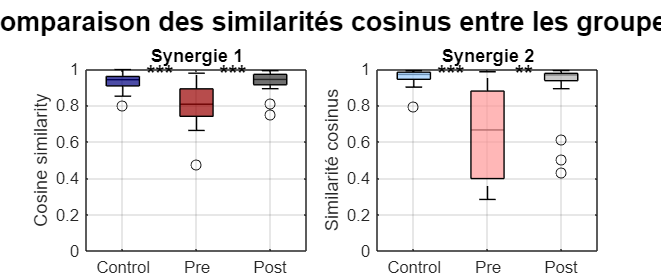


% ================== BOXPLOTS COMPARATIFS AVEC ÉTOILES ===================

% Données de similarité cosinus pour chaque groupe et synergie
group_labels = {'Control', 'Pre', 'Post'};

% Création d'une figure avec titre global
figure('Position', [100, 100, 1200, 500]);
sgtitle('Comparaison des similarités cosinus entre les groupes', 'FontSize', 16, 'FontWeight', 'bold');

% Synergie 1
subplot(1,2,1)
boxplot([sim_asymp_S1_vs_mean_S1; similarity_pre_S1_asymp_S1; similarity_post_S1_asymp_S1], ...
    [ones(size(sim_asymp_S1_vs_mean_S1));
     2*ones(size(similarity_pre_S1_asymp_S1));
     3*ones(size(similarity_post_S1_asymp_S1))], ...
     'Labels', group_labels, 'Colors', 'k', 'Symbol', 'o');

h = findobj(gca,'Tag','Box');
patch(get(h(1),'XData'),get(h(1),'YData'),dark_black,'FaceAlpha',0.7);
patch(get(h(2),'XData'),get(h(2),'YData'),dark_red,'FaceAlpha',0.7);
patch(get(h(3),'XData'),get(h(3),'YData'),dark_blue,'FaceAlpha',0.7);

title('Synergie 1', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Cosine similarity', 'FontSize', 10);
ylim([0 1.0]);
grid on;
set(gca, 'FontSize', 10);

% Ajout d'annotations pour les p-values (Synergie 1)
% Astérisques pour indiquer la significativité
hold on;
y_max = 0.97;

% Asymp vs Pre (S1)
if p_values_asymp_pre(1) < 0.001
    text(1.5, y_max, '***', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
elseif p_values_asymp_pre(1) < 0.01
    text(1.5, y_max, '**', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
elseif p_values_asymp_pre(1) < 0.05
    text(1.5, y_max, '*', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
end

% Asymp vs Post (S1)
if p_values_asymp_post(1) < 0.001
    text(2, y_max, '***', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
elseif p_values_asymp_post(1) < 0.01
    text(2, y_max, '**', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
elseif p_values_asymp_post(1) < 0.05
    text(2, y_max, '*', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
end

% Pre vs Post (S1)
if p_values_pre_post(1) < 0.001
    text(2.5, y_max, '***', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
elseif p_values_pre_post(1) < 0.01
    text(2.5, y_max, '**', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
elseif p_values_pre_post(1) < 0.05
    text(2.5, y_max, '*', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
end

% Synergie 2
subplot(1,2,2)
boxplot([sim_asymp_S2_vs_mean_S2; similarity_pre_S2_asymp_S2; similarity_post_S2_asymp_S2], ...
    [ones(size(sim_asymp_S2_vs_mean_S2));
     2*ones(size(similarity_pre_S2_asymp_S2));
     3*ones(size(similarity_post_S2_asymp_S2))], ...
     'Labels', group_labels, 'Colors', 'k', 'Symbol', 'o');

h = findobj(gca,'Tag','Box');
patch(get(h(1),'XData'),get(h(1),'YData'),light_black,'FaceAlpha',0.7);
patch(get(h(2),'XData'),get(h(2),'YData'),light_red,'FaceAlpha',0.7);
patch(get(h(3),'XData'),get(h(3),'YData'),light_blue,'FaceAlpha',0.7);

title('Synergie 2', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Similarité cosinus', 'FontSize', 10);
ylim([0 1.0]);
grid on;
set(gca, 'FontSize', 10);

% Ajout d'annotations pour les p-values (Synergie 2)
hold on;

% Asymp vs Pre (S2)
if p_values_asymp_pre(2) < 0.001
    text(1.5, y_max, '***', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
elseif p_values_asymp_pre(2) < 0.01
    text(1.5, y_max, '**', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
elseif p_values_asymp_pre(2) < 0.05
    text(1.5, y_max, '*', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
end

% Asymp vs Post (S2)
if p_values_asymp_post(2) < 0.001
    text(2, y_max, '***', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
elseif p_values_asymp_post(2) < 0.01
    text(2, y_max, '**', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
elseif p_values_asymp_post(2) < 0.05
    text(2, y_max, '*', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
end

% Pre vs Post (S2)
if p_values_pre_post(2) < 0.001
    text(2.5, y_max, '***', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
elseif p_values_pre_post(2) < 0.01
    text(2.5, y_max, '**', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
elseif p_values_pre_post(2) < 0.05
    text(2.5, y_max, '*', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
end

% Ajout d'une légende globale pour les étoiles de significativité
annotation('textbox', [0.5, 0.01, 0, 0], 'String', '* p<0.05, ** p<0.01, *** p<0.001', ...
    'HorizontalAlignment', 'center', 'EdgeColor', 'none', 'FontSize', 12, 'FontWeight', 'bold');

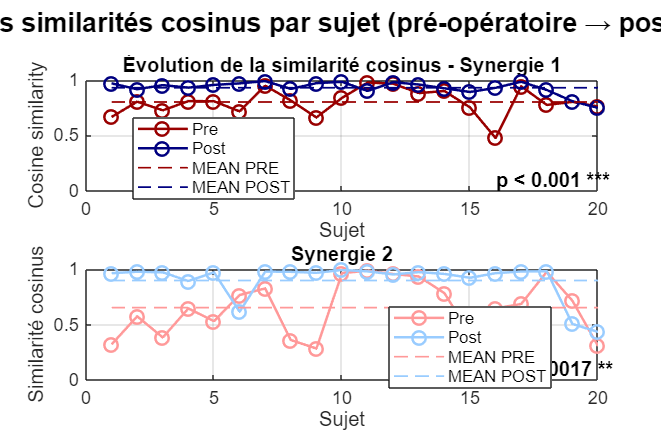


%% Ajout d'une figure avec évolution des similarités individuelles

% Créer une figure pour montrer l'évolution des similarités individuelles
figure('Position', [100, 100, 1200, 800]);
sgtitle('Évolution des similarités cosinus par sujet (pré-opératoire → post-opératoire)', 'FontSize', 16, 'FontWeight', 'bold');

% Synergie 1
subplot(2,1,1)
plot(1:n_pre_post, similarity_pre_S1_asymp_S1, 'o-', 'Color', dark_red, 'LineWidth', 1.5, 'MarkerSize', 8);
hold on
plot(1:n_pre_post, similarity_post_S1_asymp_S1, 'o-', 'Color', dark_blue, 'LineWidth', 1.5, 'MarkerSize', 8);
plot([1 n_pre_post], [mean(similarity_pre_S1_asymp_S1) mean(similarity_pre_S1_asymp_S1)], '--', 'Color', dark_red, 'LineWidth', 1);
plot([1 n_pre_post], [mean(similarity_post_S1_asymp_S1) mean(similarity_post_S1_asymp_S1)], '--', 'Color', dark_blue, 'LineWidth', 1);
ylim([0 1.0]);
title('Évolution de la similarité cosinus - Synergie 1', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Sujet', 'FontSize', 12);
ylabel('Cosine similarity', 'FontSize', 11);
legend('Pre', 'Post', 'MEAN PRE', 'MEAN POST', 'Location', 'best', 'FontSize', 10);
grid on;
set(gca, 'FontSize', 11);

% Ajouter le p-value
if p_values_pre_post(1) < 0.05
    if p_values_pre_post(1) < 0.001
        sig_text = 'p < 0.001 ***';
    elseif p_values_pre_post(1) < 0.01
        sig_text = ['p = ' num2str(p_values_pre_post(1), '%.4f') ' **'];
    else
        sig_text = ['p = ' num2str(p_values_pre_post(1), '%.4f') ' *'];
    end
else
    sig_text = ['p = ' num2str(p_values_pre_post(1), '%.4f') ' (NS)'];
end
text(n_pre_post*0.8, 0.1, sig_text, 'FontSize', 12, 'FontWeight', 'bold');

% Synergie 2
subplot(2,1,2)
plot(1:n_pre_post, similarity_pre_S2_asymp_S2, 'o-', 'Color', light_red, 'LineWidth', 1.5, 'MarkerSize', 8);
hold on
plot(1:n_pre_post, similarity_post_S2_asymp_S2, 'o-', 'Color', light_blue, 'LineWidth', 1.5, 'MarkerSize', 8);
plot([1 n_pre_post], [mean(similarity_pre_S2_asymp_S2) mean(similarity_pre_S2_asymp_S2)], '--', 'Color', light_red, 'LineWidth', 1);
plot([1 n_pre_post], [mean(similarity_post_S2_asymp_S2) mean(similarity_post_S2_asymp_S2)], '--', 'Color', light_blue, 'LineWidth', 1);
ylim([0 1.0]);
title('Synergie 2', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Sujet', 'FontSize', 12);
ylabel('Similarité cosinus', 'FontSize', 12);
legend('Pre', 'Post', 'MEAN PRE', 'MEAN POST', 'Location', 'best', 'FontSize', 10);
grid on;
set(gca, 'FontSize', 11);

% Ajouter le p-value
if p_values_pre_post(2) < 0.05
    if p_values_pre_post(2) < 0.001
        sig_text = 'p < 0.001 ***';
    elseif p_values_pre_post(2) < 0.01
        sig_text = ['p = ' num2str(p_values_pre_post(2), '%.4f') ' **'];
    else
        sig_text = ['p = ' num2str(p_values_pre_post(2), '%.4f') ' *'];
    end
else
    sig_text = ['p = ' num2str(p_values_pre_post(2), '%.4f') ' (NS)'];
end
text(n_pre_post*0.8, 0.1, sig_text, 'FontSize', 12, 'FontWeight', 'bold');


%% Tableau récapitulatif pour la publication

% Création d'un tableau avec les valeurs pour la publication
data_table = table();
data_table.Comparison = {'S1 asymptomatique vs S1 pré-op'; 'S1 asymptomatique vs S1 post-op'; 'S1 pré-op vs S1 post-op'; ...
                         'S2 asymptomatique vs S2 pré-op'; 'S2 asymptomatique vs S2 post-op'; 'S2 pré-op vs S2 post-op'};
data_table.MeanSimilarity = [mean(sim_asymp_S1_vs_mean_S1); mean(similarity_pre_S1_asymp_S1); ...
                           mean(similarity_post_S1_asymp_S1); mean(sim_asymp_S2_vs_mean_S2); ...
                           mean(similarity_pre_S2_asymp_S2); mean(similarity_post_S2_asymp_S2)];
data_table.SD = [std(sim_asymp_S1_vs_mean_S1); std(similarity_pre_S1_asymp_S1); ...
                std(similarity_post_S1_asymp_S1); std(sim_asymp_S2_vs_mean_S2); ...
                std(similarity_pre_S2_asymp_S2); std(similarity_post_S2_asymp_S2)];
data_table.pValue = [NaN; p_values_asymp_pre(1); p_values_asymp_post(1); NaN; p_values_asymp_pre(2); p_values_asymp_post(2)];
data_table.Significance = cell(6, 1);

% Ajouter les symboles de significativité
for i = 1:6
    if isnan(data_table.pValue(i))
        data_table.Significance{i} = '-';
    elseif data_table.pValue(i) < 0.001
        data_table.Significance{i} = '***';
    elseif data_table.pValue(i) < 0.01
        data_table.Significance{i} = '**';
    elseif data_table.pValue(i) < 0.05
        data_table.Significance{i} = '*';
    else
        data_table.Significance{i} = 'NS';
    end
end

% Afficher le tableau
disp(' ');

disp('TABLEAU RÉCAPITULATIF DES RÉSULTATS POUR PUBLICATION');

TABLEAU RÉCAPITULATIF DES RÉSULTATS POUR PUBLICATION


disp('=====================================================');

disp(data_table);

                Comparison                 MeanSimilarity       SD         pValue      Significance
    ___________________________________    ______________    ________    __________    ____________

    {'S1 asymptomatique vs S1 pré-op' }       0.93114        0.049431           NaN      {'-'  }   
    {'S1 asymptomatique vs S1 post-op'}       0.80199         0.12089     0.0003048      {'***'}   
    {'S1 pré-op vs S1 post-op'        }       0.93013        0.060472       0.83923      {'NS' }   
    {'S2 asymptomatique vs S2 pré-op' }       0.95453        0.045508           NaN      {'-'  }   
    {'S2 asymptomatique vs S2 post-op'}       0.65216         0.24577    4.6804e-05      {'***'}   
    {'S2 pré-op vs S2 post-op'        }       0.89643         0.16739       0.45695      {'NS' }   




% Création d'un tableau pour les résultats appariés
paired_table = table();
paired_table.Comparison = {'S1 pré-op vs S1 post-op'; 'S2 pré-op vs S2 post-op'};
paired_table.MeanDifference = [mean(similarity_post_S1_asymp_S1 - similarity_pre_S1_asymp_S1); ...
                              mean(similarity_post_S2_asymp_S2 - similarity_pre_S2_asymp_S2)];
paired_table.SD = [std(similarity_post_S1_asymp_S1 - similarity_pre_S1_asymp_S1); ...
                  std(similarity_post_S2_asymp_S2 - similarity_pre_S2_asymp_S2)];
paired_table.pValue = [p_values_pre_post(1); p_values_pre_post(2)];
paired_table.Significance = cell(2, 1);

% Ajouter les symboles de significativité
for i = 1:2
    if paired_table.pValue(i) < 0.001
        paired_table.Significance{i} = '***';
    elseif paired_table.pValue(i) < 0.01
        paired_table.Significance{i} = '**';
    elseif paired_table.pValue(i) < 0.05
        paired_table.Significance{i} = '*';
    else
        paired_table.Significance{i} = 'NS';
    end
end

% Afficher le tableau des résultats appariés
disp(' ');

disp('RÉSULTATS DES TESTS APPARIÉS (PRÉ-OP VS POST-OP)');

RÉSULTATS DES TESTS APPARIÉS (PRÉ-OP VS POST-OP)


disp('================================================');

disp(paired_table);

            Comparison             MeanDifference      SD         pValue      Significance
    ___________________________    ______________    _______    __________    ____________

    {'S1 pré-op vs S1 post-op'}       0.12814        0.12836    0.00033845      {'***'}   
    {'S2 pré-op vs S2 post-op'}       0.24427        0.27181      0.001713      {'**' }   




% Légende finale
fprintf('\nLégende: NS = Non Significatif (p > 0.05)\n');


Légende: NS = Non Significatif (p > 0.05)


fprintf('         * = Significatif (p < 0.05)\n');

         * = Significatif (p < 0.05)


fprintf('         ** = Hautement significatif (p < 0.01)\n');

         ** = Hautement significatif (p < 0.01)


fprintf('         *** = Très significatif (p < 0.001)\n\n');

         *** = Très significatif (p < 0.001)



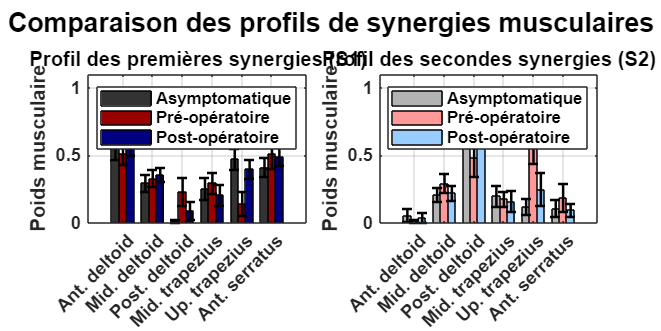


%% Affichage des profils moyens des synergies (version améliorée)
% Figure combinée pour les profils moyens de synergies avec comparaison 
% entre les trois groupes (asymptomatique, pré-op, post-op)

figure('Position', [100, 100, 1200, 600]);
sgtitle('Comparaison des profils de synergies musculaires', 'FontSize', 16, 'FontWeight', 'bold');

% Calcul des moyennes pour les synergies pré-opératoires
mean_synergy1_pre = mean(synergy1_pre, 2);
std_synergy1_pre = std(synergy1_pre, 0, 2);
sem_synergy1_pre = std_synergy1_pre / sqrt(n_pre_post);
IC_synergy1_pre = t_val * sem_synergy1_pre;

mean_synergy2_pre = mean(synergy2_pre, 2);
std_synergy2_pre = std(synergy2_pre, 0, 2);
sem_synergy2_pre = std_synergy2_pre / sqrt(n_pre_post);
IC_synergy2_pre = t_val * sem_synergy2_pre;

% Calcul des moyennes pour les synergies post-opératoires
mean_synergy1_post = mean(synergy1_post, 2);
std_synergy1_post = std(synergy1_post, 0, 2);
sem_synergy1_post = std_synergy1_post / sqrt(n_pre_post);
IC_synergy1_post = t_val * sem_synergy1_post;

mean_synergy2_post = mean(synergy2_post, 2);
std_synergy2_post = std(synergy2_post, 0, 2);
sem_synergy2_post = std_synergy2_post / sqrt(n_pre_post);
IC_synergy2_post = t_val * sem_synergy2_post;

% Synergie 1
subplot(1,2,1)
x = 1:n_muscles;
bar_width = 0.25;
positions1 = x - bar_width;
positions2 = x;
positions3 = x + bar_width;

bar(positions1, mean_synergy1_asymp, bar_width, 'FaceColor', dark_black);
hold on
bar(positions2, mean_synergy1_pre, bar_width, 'FaceColor', dark_red);
bar(positions3, mean_synergy1_post, bar_width, 'FaceColor', dark_blue);

% Ajout des barres d'erreur (IC 95%)
errorbar(positions1, mean_synergy1_asymp, IC_synergy1_asymp, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(positions2, mean_synergy1_pre, IC_synergy1_pre, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(positions3, mean_synergy1_post, IC_synergy1_post, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

title('Profil des premières synergies (S1)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Poids musculaire', 'FontSize', 12, 'FontWeight', 'bold');
xticks(x);
xticklabels(noms_muscles);
xtickangle(45);
ylim([0 1.1]);
grid on;
legend('Asymptomatique', 'Pré-opératoire', 'Post-opératoire', 'Location', 'northeast', 'FontSize', 10);
set(gca, 'FontSize', 11, 'FontWeight', 'bold');

% Synergie 2
subplot(1,2,2)
bar(positions1, mean_synergy2_asymp, bar_width, 'FaceColor', light_black);
hold on
bar(positions2, mean_synergy2_pre, bar_width, 'FaceColor', light_red);
bar(positions3, mean_synergy2_post, bar_width, 'FaceColor', light_blue);

% Ajout des barres d'erreur (IC 95%)
errorbar(positions1, mean_synergy2_asymp, IC_synergy2_asymp, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(positions2, mean_synergy2_pre, IC_synergy2_pre, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(positions3, mean_synergy2_post, IC_synergy2_post, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

title('Profil des secondes synergies (S2)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Poids musculaire', 'FontSize', 12, 'FontWeight', 'bold');
xticks(x);
xticklabels(noms_muscles);
xtickangle(45);
ylim([0 1.1]);
grid on;
legend('Asymptomatique', 'Pré-opératoire', 'Post-opératoire', 'Location', 'northeast', 'FontSize', 10);
set(gca, 'FontSize', 11, 'FontWeight', 'bold');


fprintf('\n===== TABLEAU RÉCAPITULATIF COMPLET =====\n\n');


===== TABLEAU RÉCAPITULATIF COMPLET =====




% Création du tableau avec toutes les valeurs individuelles
fprintf('VALEURS INDIVIDUELLES DE SIMILARITÉ COSINUS\n');

VALEURS INDIVIDUELLES DE SIMILARITÉ COSINUS


fprintf('==========================================\n\n');


% Tableau pour Synergie 1
fprintf('SYNERGIE 1 - Similarité cosinus individuelle\n');

SYNERGIE 1 - Similarité cosinus individuelle


fprintf('---------------------------------------------\n');

---------------------------------------------


fprintf('| Sujet | Asymptomatique | Pré-opératoire | Post-opératoire |\n');

| Sujet | Asymptomatique | Pré-opératoire | Post-opératoire |


fprintf('---------------------------------------------\n');

---------------------------------------------



max_subjects = max([n_asymp, n_pre_post, n_pre_post]);
for i = 1:max_subjects
    fprintf('| %2d    |', i);
    
    if i <= n_asymp
        fprintf('     %.4f     |', sim_asymp_S1_vs_mean_S1(i));
    else
        fprintf('       -       |');
    end
    
    if i <= n_pre_post
        fprintf('     %.4f     |', similarity_pre_S1_asymp_S1(i));
    else
        fprintf('       -       |');
    end
    
    if i <= n_pre_post
        fprintf('      %.4f      |', similarity_post_S1_asymp_S1(i));
    else
        fprintf('        -        |');
    end
    
    fprintf('\n');
end

|  1    |

     0.9287     |

     0.6669     |

      0.9699      |

|  2    |

     0.9582     |

     0.8049     |

      0.9168      |

|  3    |

     0.9275     |

     0.7265     |

      0.9540      |

|  4    |

     0.9559     |

     0.8101     |

      0.9311      |

|  5    |

     0.9014     |

     0.8085     |

      0.9558      |

|  6    |

     0.9599     |

     0.7171     |

      0.9695      |

|  7    |

     0.9777     |

     0.9492     |

      0.9907      |

|  8    |

     0.8970     |

     0.8157     |

      0.9195      |

|  9    |

     0.9245     |

     0.6627     |

      0.9716      |

| 10    |

     0.8660     |

     0.8389     |

      0.9837      |

| 11    |

     0.9321     |

     0.9773     |

      0.9012      |

| 12    |

     0.8505     |

     0.9667     |

      0.9801      |

| 13    |

     0.9587     |

     0.8818     |

      0.9591      |

| 14    |

     0.9940     |

     0.9009     |

      0.9253      |

| 15    |

     0.9505     |

     0.7532     |

      0.8921      |

| 16    |

     0.9965     |

     0.4775     |

      0.9297      |

| 17    |

     0.9545     |

     0.9424     |

      0.9847      |

| 18    |

     0.9119     |

     0.7751     |

      0.9100      |

| 19    |

     0.9764     |

     0.8032     |

      0.8091      |

| 20    |

     0.8011     |

     0.7611     |

      0.7487      |

fprintf('---------------------------------------------\n\n');

---------------------------------------------




% Tableau pour Synergie 2
fprintf('SYNERGIE 2 - Similarité cosinus individuelle\n');

SYNERGIE 2 - Similarité cosinus individuelle


fprintf('---------------------------------------------\n');

---------------------------------------------


fprintf('| Sujet | Asymptomatique | Pré-opératoire | Post-opératoire |\n');

| Sujet | Asymptomatique | Pré-opératoire | Post-opératoire |


fprintf('---------------------------------------------\n');

---------------------------------------------



for i = 1:max_subjects
    fprintf('| %2d    |', i);
    
    if i <= n_asymp
        fprintf('     %.4f     |', sim_asymp_S2_vs_mean_S2(i));
    else
        fprintf('       -       |');
    end
    
    if i <= n_pre_post
        fprintf('     %.4f     |', similarity_pre_S2_asymp_S2(i));
    else
        fprintf('       -       |');
    end
    
    if i <= n_pre_post
        fprintf('      %.4f      |', similarity_post_S2_asymp_S2(i));
    else
        fprintf('        -        |');
    end
    
    fprintf('\n');
end

|  1    |

     0.9383     |

     0.3207     |

      0.9618      |

|  2    |

     0.9718     |

     0.5737     |

      0.9757      |

|  3    |

     0.9686     |

     0.3832     |

      0.9697      |

|  4    |

     0.9004     |

     0.6448     |

      0.8917      |

|  5    |

     0.9564     |

     0.5301     |

      0.9702      |

|  6    |

     0.9837     |

     0.7656     |

      0.6150      |

|  7    |

     0.9232     |

     0.8251     |

      0.9765      |

|  8    |

     0.9481     |

     0.3597     |

      0.9749      |

|  9    |

     0.7933     |

     0.2835     |

      0.9657      |

| 10    |

     0.9203     |

     0.9628     |

      0.9916      |

| 11    |

     0.9817     |

     0.9849     |

      0.9785      |

| 12    |

     0.9740     |

     0.9551     |

      0.9509      |

| 13    |

     0.9637     |

     0.9325     |

      0.9719      |

| 14    |

     0.9907     |

     0.7828     |

      0.9559      |

| 15    |

     0.9753     |

     0.4132     |

      0.9208      |

| 16    |

     0.9846     |

     0.6446     |

      0.9624      |

| 17    |

     0.9733     |

     0.6852     |

      0.9775      |

| 18    |

     0.9674     |

     0.9747     |

      0.9800      |

| 19    |

     0.9843     |

     0.7142     |

      0.5047      |

| 20    |

     0.9916     |

     0.3068     |

      0.4333      |

fprintf('---------------------------------------------\n\n');

---------------------------------------------




% Statistiques descriptives par groupe
fprintf('STATISTIQUES DESCRIPTIVES PAR GROUPE\n');

STATISTIQUES DESCRIPTIVES PAR GROUPE


fprintf('====================================\n\n');


fprintf('SYNERGIE 1\n');

SYNERGIE 1


fprintf('----------\n');

----------


fprintf('| Groupe          | N  | Moyenne | Écart-type | Min    | Max    |\n');

| Groupe          | N  | Moyenne | Écart-type | Min    | Max    |


fprintf('----------\n');

----------


fprintf('| Asymptomatique  | %2d | %.4f  | %.4f     | %.4f | %.4f |\n', ...
    n_asymp, mean(sim_asymp_S1_vs_mean_S1), std(sim_asymp_S1_vs_mean_S1), ...
    min(sim_asymp_S1_vs_mean_S1), max(sim_asymp_S1_vs_mean_S1));

| Asymptomatique  | 20 | 0.9311  | 0.0494     | 0.8011 | 0.9965 |


fprintf('| Pré-opératoire  | %2d | %.4f  | %.4f     | %.4f | %.4f |\n', ...
    n_pre_post, mean(similarity_pre_S1_asymp_S1), std(similarity_pre_S1_asymp_S1), ...
    min(similarity_pre_S1_asymp_S1), max(similarity_pre_S1_asymp_S1));

| Pré-opératoire  | 20 | 0.8020  | 0.1209     | 0.4775 | 0.9773 |


fprintf('| Post-opératoire | %2d | %.4f  | %.4f     | %.4f | %.4f |\n', ...
    n_pre_post, mean(similarity_post_S1_asymp_S1), std(similarity_post_S1_asymp_S1), ...
    min(similarity_post_S1_asymp_S1), max(similarity_post_S1_asymp_S1));

| Post-opératoire | 20 | 0.9301  | 0.0605     | 0.7487 | 0.9907 |


fprintf('----------\n\n');

----------




fprintf('SYNERGIE 2\n');

SYNERGIE 2


fprintf('----------\n');

----------


fprintf('| Groupe          | N  | Moyenne | Écart-type | Min    | Max    |\n');

| Groupe          | N  | Moyenne | Écart-type | Min    | Max    |


fprintf('----------\n');

----------


fprintf('| Asymptomatique  | %2d | %.4f  | %.4f     | %.4f | %.4f |\n', ...
    n_asymp, mean(sim_asymp_S2_vs_mean_S2), std(sim_asymp_S2_vs_mean_S2), ...
    min(sim_asymp_S2_vs_mean_S2), max(sim_asymp_S2_vs_mean_S2));

| Asymptomatique  | 20 | 0.9545  | 0.0455     | 0.7933 | 0.9916 |


fprintf('| Pré-opératoire  | %2d | %.4f  | %.4f     | %.4f | %.4f |\n', ...
    n_pre_post, mean(similarity_pre_S2_asymp_S2), std(similarity_pre_S2_asymp_S2), ...
    min(similarity_pre_S2_asymp_S2), max(similarity_pre_S2_asymp_S2));

| Pré-opératoire  | 20 | 0.6522  | 0.2458     | 0.2835 | 0.9849 |


fprintf('| Post-opératoire | %2d | %.4f  | %.4f     | %.4f | %.4f |\n', ...
    n_pre_post, mean(similarity_post_S2_asymp_S2), std(similarity_post_S2_asymp_S2), ...
    min(similarity_post_S2_asymp_S2), max(similarity_post_S2_asymp_S2));

| Post-opératoire | 20 | 0.8964  | 0.1674     | 0.4333 | 0.9916 |


fprintf('----------\n\n');

----------




% Résumé des tests statistiques 
fprintf('RÉSUMÉ DES TESTS STATISTIQUES\n');

RÉSUMÉ DES TESTS STATISTIQUES


fprintf('=============================\n\n');


fprintf('ANOVA À UN FACTEUR\n');

ANOVA À UN FACTEUR


fprintf('------------------\n');

------------------


fprintf('Synergie 1: F(%d,%d) = %.3f, p = %.4f ', ...
    df_between_S1, df_within_S1, F_stat_S1, p_anova_S1);

Synergie 1: F(2,57) = 15.979, p = 0.0000 

if p_anova_S1 < 0.05
    fprintf('(significatif)\n');
else
    fprintf('(non significatif)\n');
end

(significatif)



fprintf('Synergie 2: F(%d,%d) = %.3f, p = %.4f ', ...
    df_between_S2, df_within_S2, F_stat_S2, p_anova_S2);

Synergie 2: F(2,57) = 17.069, p = 0.0000 

if p_anova_S2 < 0.05
    fprintf('(significatif)\n');
else
    fprintf('(non significatif)\n');
end

(significatif)


fprintf('\n');

fprintf('TESTS T INDÉPENDANTS (Asymptomatiques vs autres groupes)\n');

TESTS T INDÉPENDANTS (Asymptomatiques vs autres groupes)


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



fprintf('S1 - Asymp vs Pré:  t-test, p = %.4f ', p_values_asymp_pre(1));

S1 - Asymp vs Pré:  t-test, p = 0.0003 

if p_values_asymp_pre(1) < 0.05
    fprintf('*\n');
else
    fprintf('\n');
end

*



fprintf('S1 - Asymp vs Post: t-test, p = %.4f ', p_values_asymp_post(1));

S1 - Asymp vs Post: t-test, p = 0.8392 

if p_values_asymp_post(1) < 0.05
    fprintf('*\n');
else
    fprintf('\n');
end

fprintf('S2 - Asymp vs Pré:  t-test, p = %.4f ', p_values_asymp_pre(2));

S2 - Asymp vs Pré:  t-test, p = 0.0000 

if p_values_asymp_pre(2) < 0.05
    fprintf('*\n');
else
    fprintf('\n');
end

*



fprintf('S2 - Asymp vs Post: t-test, p = %.4f ', p_values_asymp_post(2));

S2 - Asymp vs Post: t-test, p = 0.4570 

if p_values_asymp_post(2) < 0.05
    fprintf('*\n');
else
    fprintf('\n');
end
fprintf('\n');

fprintf('TESTS T APPARIÉS (Pré-opératoire vs Post-opératoire)\n');

TESTS T APPARIÉS (Pré-opératoire vs Post-opératoire)


fprintf('----------------------------------------------------\n');

----------------------------------------------------



fprintf('S1 - Pré vs Post: t-test apparié, p = %.4f ', p_values_pre_post(1));

S1 - Pré vs Post: t-test apparié, p = 0.0003 

if p_values_pre_post(1) < 0.05
    fprintf('*\n');
else
    fprintf('\n');
end

*



fprintf('S2 - Pré vs Post: t-test apparié, p = %.4f ', p_values_pre_post(2));

S2 - Pré vs Post: t-test apparié, p = 0.0017 

if p_values_pre_post(2) < 0.05
    fprintf('*\n');
else
    fprintf('\n');
end

*


fprintf('\n');


% Création d'un fichier CSV avec toutes les données (optionnel)
fprintf('SAUVEGARDE DES DONNÉES\n');

SAUVEGARDE DES DONNÉES


fprintf('=====================\n');


% Création d'une matrice avec toutes les données
all_data = [];
all_labels = {};
subject_ids = [];

% Ajout des données asymptomatiques
for i = 1:n_asymp
    all_data = [all_data; sim_asymp_S1_vs_mean_S1(i), sim_asymp_S2_vs_mean_S2(i)];
    all_labels{end+1} = 'Asymptomatique';
    subject_ids = [subject_ids; i];
end

% Ajout des données pré-opératoires
for i = 1:n_pre_post
    all_data = [all_data; similarity_pre_S1_asymp_S1(i), similarity_pre_S2_asymp_S2(i)];
    all_labels{end+1} = 'Pre-operatoire';
    subject_ids = [subject_ids; i];
end

% Ajout des données post-opératoires
for i = 1:n_pre_post
    all_data = [all_data; similarity_post_S1_asymp_S1(i), similarity_post_S2_asymp_S2(i)];
    all_labels{end+1} = 'Post-operatoire';
    subject_ids = [subject_ids; i];
end

% Création du tableau final
final_table = table(subject_ids, all_labels', all_data(:,1), all_data(:,2), ...
    'VariableNames', {'Sujet', 'Groupe', 'Similarite_S1', 'Similarite_S2'});

% Sauvegarde du tableau
writetable(final_table, 'resultats_similarites_cosinus.csv');
fprintf('Données sauvegardées dans le fichier: resultats_similarites_cosinus.csv\n\n');

Données sauvegardées dans le fichier: resultats_similarites_cosinus.csv




% Affichage du tableau final dans la console
fprintf('TABLEAU FINAL POUR EXPORT\n');

TABLEAU FINAL POUR EXPORT


fprintf('=========================\n');

disp(final_table);

    Sujet          Groupe           Similarite_S1    Similarite_S2
    _____    ___________________    _____________    _____________

      1      {'Asymptomatique' }       0.92872          0.93826   
      2      {'Asymptomatique' }       0.95819           0.9718   
      3      {'Asymptomatique' }       0.92754          0.96865   
      4      {'Asymptomatique' }       0.95594          0.90038   
      5      {'Asymptomatique' }       0.90136          0.95642   
      6      {'Asymptomatique' }       0.95988          0.98368   
      7      {'Asymptomatique' }       0.97769          0.92321   
      8      {'Asymptomatique' }       0.89699          0.94809   
      9      {'Asymptomatique' }       0.92447          0.79332   
     10      {'Asymptomatique' }       0.86596           0.9203   
     11      {'Asymptomatique' }       0.93214          0.9


fprintf('\n=== ANALYSE STATISTIQUE COMPLÈTE TERMINÉE ===\n');


=== ANALYSE STATISTIQUE COMPLÈTE TERMINÉE ===



% Affichage d'un message de conclusion
fprintf('\n Analyse terminée\n');


 Analyse terminée


**Figure article**

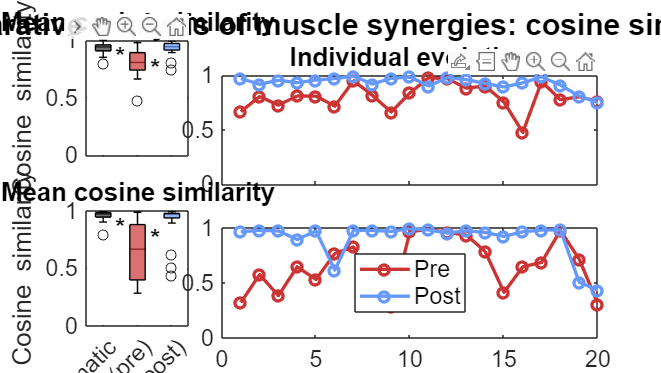

%% FIGURE 2x2 POUR ARTICLE - SYNERGIES 1 ET 2
% Figure combinée avec boxplots (colonne 1) et évolution individuelle (colonne 2)

figure('Position', [100, 100, 1600, 900]);
sgtitle('Comparative analysis of muscle synergies: cosine similarity', 'FontSize', 18, 'FontWeight', 'bold');

% Définition des couleurs
darker_red = [0.8, 0.2, 0.2];  % Rouge plus foncé
light_blue = [0.4, 0.6, 1];    % Bleu plus clair

% ========== SYNERGIE 1 ==========

% Subplot 1,1: Boxplot Synergie 1 (plus petit)
subplot(2,4,1)
boxplot([sim_asymp_S1_vs_mean_S1; similarity_pre_S1_asymp_S1; similarity_post_S1_asymp_S1], ...
    [ones(size(sim_asymp_S1_vs_mean_S1));
     2*ones(size(similarity_pre_S1_asymp_S1));
     3*ones(size(similarity_post_S1_asymp_S1))], ...
     'Labels', {'Control', 'Pre', 'Post'}, 'Colors', 'k', 'Symbol', 'o');

% Coloration des boxplots
h = findobj(gca,'Tag','Box');
patch(get(h(1),'XData'),get(h(1),'YData'),light_blue,'FaceAlpha',0.7);  % Post
patch(get(h(2),'XData'),get(h(2),'YData'),darker_red,'FaceAlpha',0.7);   % Pre
patch(get(h(3),'XData'),get(h(3),'YData'),dark_black,'FaceAlpha',0.7); % Control

title('Mean cosine similarity', 'FontSize', 16, 'FontWeight', 'bold');
ylabel({'{\bf Synergy 1}',' ', 'Cosine similarity'}, 'Interpreter', 'tex', 'FontSize', 14);
ylim([0 1.0]);
grid off;
set(gca, 'FontSize', 14);
set(gca, 'XTickLabel', []);       % Cache les mots (Control, Pre, Post)
xlabel('');                       % Supprime le label X s’il y en a un

% Ajout des étoiles de significativité
hold on;

% Comparaison Control vs Pre (position 1.5)
if p_values_asymp_pre(1) < 0.05
    y_pos = 0.8;
        text(1.5, y_pos+0.05, '*', 'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold');
    elseif p_values_asymp_pre(1) < 0.01
        text(1.5, y_pos+0.05, '**', 'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold');
else
        text(1.5, y_pos+0.05, '*', 'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold');
end

% Comparaison Pre vs Post (position 2.5)
if p_values_pre_post(1) < 0.05
    y_pos = 0.7;
    if p_values_pre_post(1) < 0.001
        text(2.5, y_pos+0.05, '*', 'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold');
    elseif p_values_pre_post(1) < 0.01
        text(2.5, y_pos+0.05, '**', 'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold');
    else
        text(2.5, y_pos+0.05, '*', 'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold');
    end
end


% Subplot 1,2-4: Évolution individuelle Synergie 1 (plus grand)
subplot(2,4,[2 3 4])
plot(1:n_pre_post, similarity_pre_S1_asymp_S1, 'o-', 'Color', darker_red, 'LineWidth', 2, 'MarkerSize', 6);
hold on
plot(1:n_pre_post, similarity_post_S1_asymp_S1, 'o-', 'Color', light_blue, 'LineWidth', 2, 'MarkerSize', 6);
ylim([0 1.0]);
title('Individual evolution', 'FontSize', 16, 'FontWeight', 'bold');
%legend('Pre-op', 'Post-op', 'Location', 'best', 'FontSize', 10);
grid off;
set(gca, 'FontSize', 14);
set(gca, 'XTickLabel', []);       % Cache les valeurs numériques de l’axe X
xlabel('');                       % Supprime le label de l’axe X


% ========== SYNERGIE 2 ==========

% Subplot 2,1: Boxplot Synergie 2 (plus petit)
subplot(2,4,5)
boxplot([sim_asymp_S2_vs_mean_S2; similarity_pre_S2_asymp_S2; similarity_post_S2_asymp_S2], ...
    [ones(size(sim_asymp_S2_vs_mean_S2));
     2*ones(size(similarity_pre_S2_asymp_S2));
     3*ones(size(similarity_post_S2_asymp_S2))], ...
     'Labels', {'Asymptomatic', 'Symptomatic (pre)', 'Symptomatic (post)'}, 'Colors', 'k', 'Symbol', 'o');

% Coloration des boxplots (mêmes couleurs que S1)
h = findobj(gca,'Tag','Box');
patch(get(h(1),'XData'),get(h(1),'YData'),light_blue,'FaceAlpha',0.7);  % Post
patch(get(h(2),'XData'),get(h(2),'YData'),darker_red,'FaceAlpha',0.7);   % Pre
patch(get(h(3),'XData'),get(h(3),'YData'),dark_black,'FaceAlpha',0.7); % Control

title('Mean cosine similarity', 'FontSize', 14, 'FontWeight', 'bold');
ylabel({'{\bf Synergy 2}',' ', 'Cosine similarity'}, 'Interpreter', 'tex', 'FontSize', 14);
ylim([0 1.0]);
grid off;
set(gca, 'FontSize', 14);

% Ajout des étoiles de significativité
hold on;
if p_values_asymp_pre(1) < 0.05
    y_pos = 0.8;
    if p_values_asymp_pre(1) < 0.001
        text(1.5, y_pos+0.05, '*', 'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold');
    elseif p_values_asymp_pre(1) < 0.01
        plot(1.5, y_pos, '*k', 'MarkerSize', 8, 'LineWidth', 1.5);
        text(1.5, y_pos+0.05, '**', 'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold');
    else
        text(1.5, y_pos+0.05, '*', 'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold');
    end
end

if p_values_pre_post(1) < 0.05
    y_pos = 0.7;
    if p_values_pre_post(1) < 0.001
        text(2.5, y_pos+0.05, '*', 'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold');
    elseif p_values_pre_post(1) < 0.01
        text(2.5, y_pos+0.05, '**', 'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold');
    else
        text(2.5, y_pos+0.05, '*', 'HorizontalAlignment', 'center', 'FontSize', 15, 'FontWeight', 'bold');
    end
end

% Subplot 2,2-4: Évolution individuelle Synergie 2 (plus grand)
subplot(2,4,[6 7 8])
plot(1:n_pre_post, similarity_pre_S2_asymp_S2, 'o-', 'Color', darker_red, 'LineWidth', 2, 'MarkerSize', 6);
hold on
plot(1:n_pre_post, similarity_post_S2_asymp_S2, 'o-', 'Color', light_blue, 'LineWidth', 2, 'MarkerSize', 6);
ylim([0 1.0]);
% title('Individual evolution', 'FontSize', 16, 'FontWeight', 'bold');
xlabel('Subject', 'FontSize', 14);
legend('Pre', 'Post', 'Location', 'best', 'FontSize', 14);
grid off;
set(gca, 'FontSize', 14);

% Ajout d'une légende globale pour les étoiles de significativité
annotation('textbox', [0.5, 0.02, 0, 0], 'String', '* p<0.05, ** p<0.01, *** p<0.001', ...
    'HorizontalAlignment', 'center', 'EdgeColor', 'none', 'FontSize', 12, 'FontWeight', 'bold');

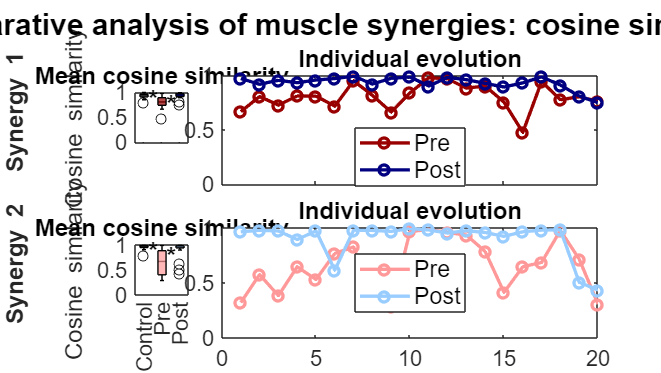


% Ajustement de l'espacement entre les subplots
set(gcf, 'PaperPositionMode', 'auto');